
% configs
cfg.fft_size = 512;
cfg.shift = cfg.fft_size/2;
cfg.fwindow = @hann;


% read audio
[ain, fs] = audioread('wav_sample/r_female_07_4ch.wav');
cfg.audio_size_origin = size(ain,1);
cfg.N = floor((cfg.audio_size_origin-cfg.fft_size)/cfg.shift)+1;

fin = zeros(cfg.fft_size, cfg.N, size(ain, 2));
for i = 0:cfg.N-1
    tmp = ain(i*cfg.shift+1:(i*cfg.shift)+cfg.fft_size, :);
    ftmp = fft(tmp, cfg.fft_size, 1);
    fin(:, i+1, :) = reshape(ftmp, cfg.fft_size, 1, []);
end

fin1 = reshape(fin(:,:,1), cfg.fft_size, cfg.N);

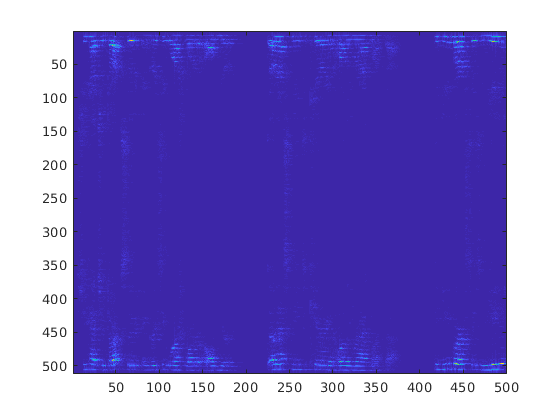

imagesc(abs(fin1))


f1 = fft(fin1(15, :));
f1d = fft([0.4 0.3 0.2 0.1], size(f1,1));
f2 = (abs(f1d)>0.1).*f1./f1d;
if2 = ifft(f2);
plot([abs(if2)' abs(fin1(15,:))'])